# Filtrar uma música usando um passa alta e faixa usando Kaiser e otimização

% EL36F - PROCESSAMENTO DIGITAL DE SINAIS TURMA: ET61           %
%                                                               
% Aluno: Pedro Henrique Garcia - 1829696                        %
%                                                               

% otimização: firpm
% kaiser: kaiser
% Criação de um filtro passa-faixa, que permite a passagem apenas da 
% faixa de frequência de um Baixo elétrico. 
% O filtro foi aplicado na música YYZ, da banda Rush, que é uma música
% conhecida pela ampla utilização do Baixo.

## Importa o arquivo

% Leitura do arquivo
[data fs] = audioread('yyz.m4a');
ch_left = data(:,1);
ch_right = data(:,2);
% Banda de passagem
fn = [41 262];
wn = fn/(fs/2);

## Filtro por meio de otimização Parks–McClellan

% Criação do filtro através de especificações
Ap=0.01;
As=70;
f=[11 41 262 292];
a=[0 1 0];
r =[(10^(Ap/20)-1)/(10^(Ap/20)+1) 10^(-As/20) (10^(Ap/20)-1)/(10^(Ap/20)+1)];
[n,fo,ao,w] = firpmord(f,a,r,fs);
f1=firpm(n,fo,ao,w);

% Filtra a música utilizando a fft
y1 = fftfilt(f1, ch_left);
y2 = fftfilt(f1, ch_right);
y = [y1 y2];

% Escreve o arquivo .flac
audiowrite('yyz_parks.flac',y,fs)

## Filtro Kaiser

% Criação do filtro
[N,Wn,BTA,FILTYPE] = kaiserord([0 41 262 280] , [0 1 0], [0.05 0.05 0.05], fs)

N = 3084

Wn =     0.0009
    0.0123


BTA = 1.5099

FILTYPE = 'DC-0'

f2 = fir1(N, Wn, FILTYPE, kaiser(N+1, BTA));

% Filtra a música utilizando a fft
y1 = fftfilt(f2, ch_left);
y2 = fftfilt(f2, ch_right);
y = [y1 y2];

% Escreve o arquivo .flac
audiowrite('yyz_kaiser.flac',y,fs)

## Plot do filtro por otimização

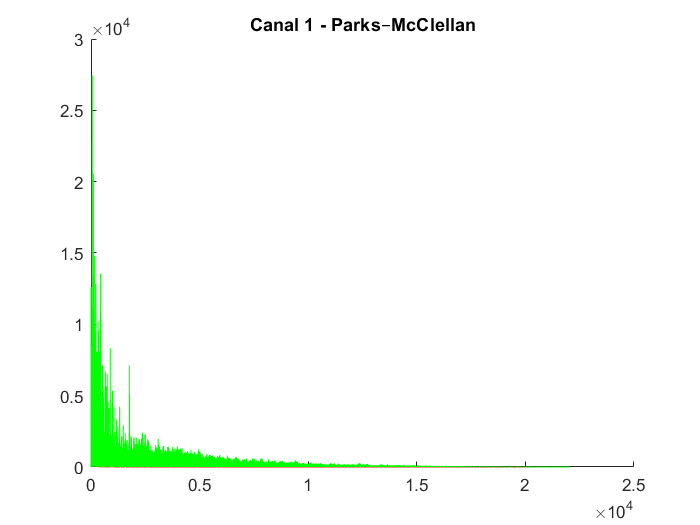

% cria o vetor de frequência
freq=0:fs/length(data(:,1)):fs-1/fs;

% frequência e verificar efetividade do filtro;
Y = [fft(y1), fft(y2)];
orig = [fft(data(:,1)) fft(data(:,2))];

figure(1)
title(['Canal 1 - Parks–McClellan'])
hold on; 
plot(freq(1:end/2+1), abs(Y(1:end/2+1, 1)), 'r');
plot(freq(1:end/2+1), abs(orig(1:end/2+1, 1)), 'g');
hold off;

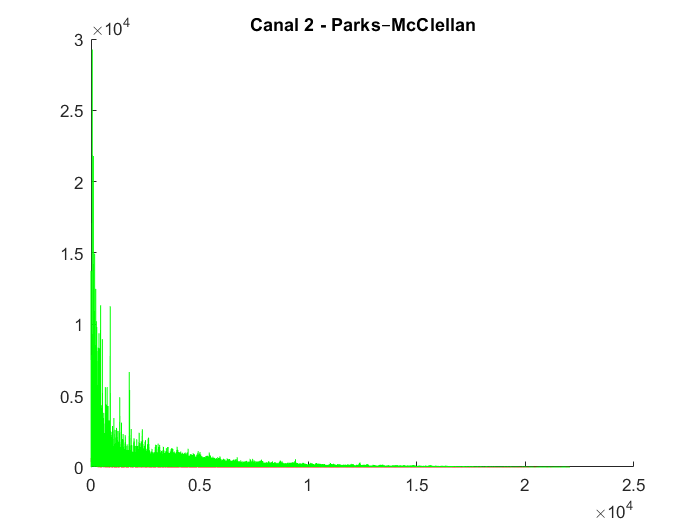


figure(2)
title(['Canal 2 - Parks–McClellan'])
hold on;
plot(freq(1:end/2+1), abs(Y(1:end/2+1, 2)), 'r');
plot(freq(1:end/2+1), abs(orig(1:end/2+1, 2)), 'g');
hold off;

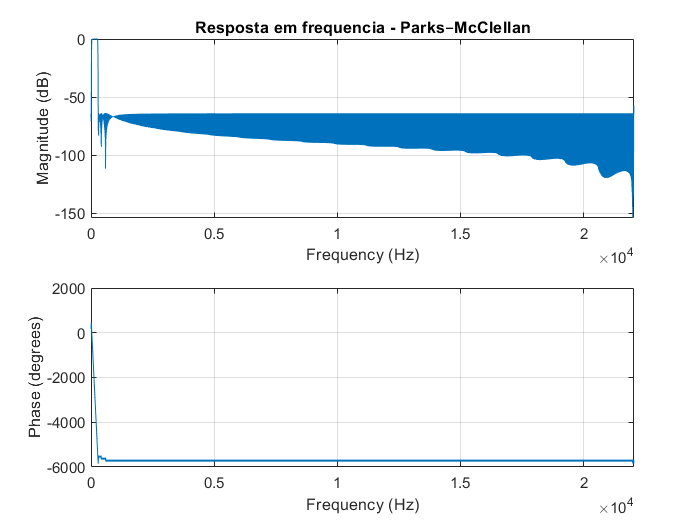


figure(3)
freqz(f1, 1, n, fs);
title(['Resposta em frequencia - Parks–McClellan'])

## Plot do filtro janela kaiser

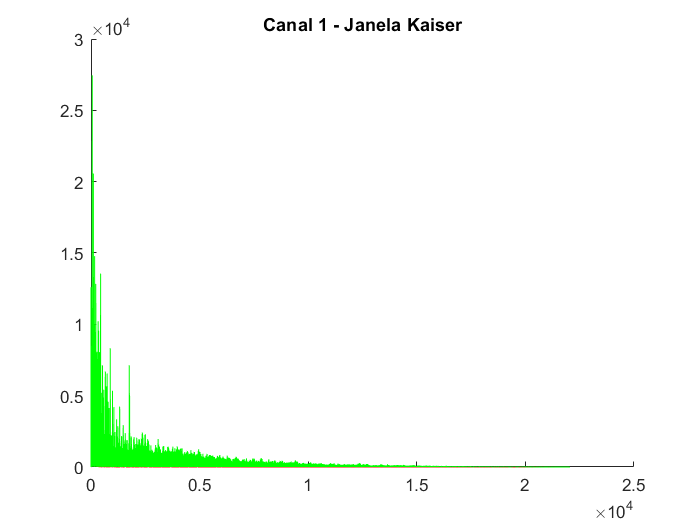

% cria o vetor de frequência
freq=0:fs/length(data(:,1)):fs-1/fs;

% frequência e verificar efetividade do filtro;
Y = [fft(y1), fft(y2)];
orig = [fft(data(:,1)) fft(data(:,2))];

figure(4)
title(['Canal 1 - Janela Kaiser'])
hold on; 
plot(freq(1:end/2+1), abs(Y(1:end/2+1, 1)), 'r');
plot(freq(1:end/2+1), abs(orig(1:end/2+1, 1)), 'g');
hold off;

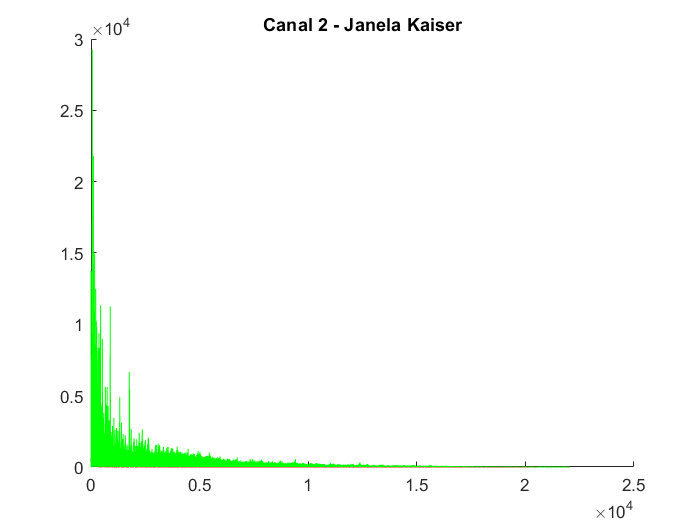


figure(5)
title(['Canal 2 - Janela Kaiser'])
hold on;
plot(freq(1:end/2+1), abs(Y(1:end/2+1, 2)), 'r');
plot(freq(1:end/2+1), abs(orig(1:end/2+1, 2)), 'g');
hold off;

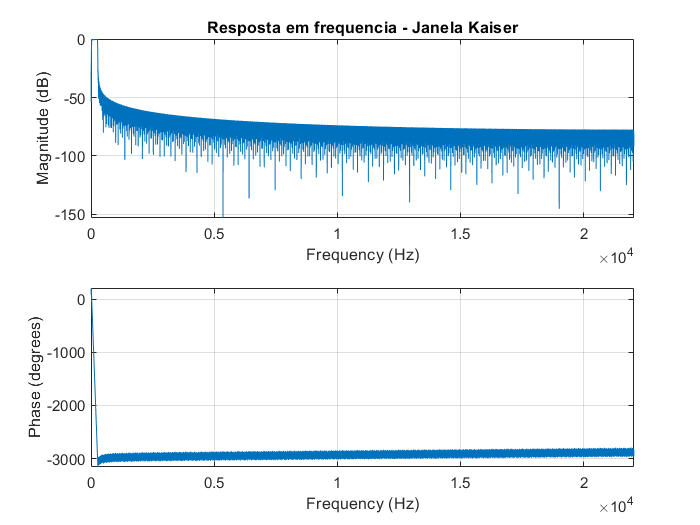


figure(6)
freqz(f2, 1, n, fs);
title(['Resposta em frequencia - Janela Kaiser'])